fp = 1; fs = 1.1203; Gp = 0.85; Gs = 0.15; % filter specifications
Wp = 2*pi*fp; Ws = 2*pi*fs;
ep = sqrt(1/Gp^2 - 1); es = sqrt(1/Gs^2 - 1);
k = Wp/Ws 

k = 0.8926

k1 = ep/es 

k1 = 0.0940

[K,Kp] = ellipk(k); % elliptic integrals K
[K1,K1p] = ellipk(k1); % elliptic integrals K1 
Nexact = (K1p/K1)/(Kp/K); N = ceil(Nexact);
N

N = 4


Ap=-20*log10(Gp);
As=-20*log10(Gs);
[z,p,H0,B,A] = ellipap2(N ,Ap,As);


syms s z;
digits(4)
analog_lpf(s)=vpa(prod((B(:,1) + B(:,2)*s + B(:,3)*s^2)./(A(:,1) + A(:,2)*s + A(:,3)*s^2)))

$$analog\_lpf(s) = \frac{0.85\,\left(0.3196\,s^{2}+1.0\right)\,\left(0.8835\,s^{2}+1.0\right)}{\left(1.6\,s^{2}+1.131\,s+1.0\right)\,\left(1.0\,s^{2}+0.06192\,s+1.0\right)}$$

analog_bsf(s) = simplify(vpa(analog_lpf((s*s + 0.5418*0.5418)/(0.5358*s))))     %bandpass transformation

$$analog\_bsf(s) = \frac{4.659e+26\,s^{8}+1.117e+27\,s^{6}+7.115e+26\,s^{4}+9.625e+25\,s^{2}+3.459e+24}{3.106e+27\,s^{8}+1.28e+27\,s^{7}+5.135e+27\,s^{6}+1.483e+27\,s^{5}+2.639e+27\,s^{4}+4.355e+26\,s^{3}+4.425e+26\,s^{2}+3.237e+25\,s+2.306e+25}$$

discrete_bsf(z) = vpa(simplify(analog_bsf((z-1)/(z+1))))         %bilinear transformation

$$discrete\_bsf(z) = \frac{2.394e+7\,z^{8}-7.782e+7\,z^{7}+1.515e+8\,z^{6}-2.181e+8\,z^{5}+2.499e+8\,z^{4}-2.181e+8\,z^{3}+1.515e+8\,z^{2}-7.782e+7\,z+2.394e+7}{1.458e+8\,z^{8}-5.301e+8\,z^{7}+1.139e+9\,z^{6}-1.65e+9\,z^{5}+1.791e+9\,z^{4}-1.427e+9\,z^{3}+8.483e+8\,z^{2}-3.385e+8\,z+8.114e+7}$$


%coeffs of analog BPF
[ns, ds] = numden(analog_bsf(s));                   %numerical simplification
ns = sym2poly(expand(ns));                          
ds = sym2poly(expand(ds));                          %collect coeffs into matrix form
k = ds(1);    
ds = ds/k;
ns = ns/k;

%coeffs of discrete BPF
[nz, dz] = numden(discrete_bsf(z));                 %numerical simplification
nz = sym2poly(expand(nz));                          
dz = sym2poly(expand(dz));                          %collect coeffs into matrix form
k = dz(1);                                          %normalisation factor
dz = dz/k;
nz = nz/k;
fvtool(nz,dz)                                       %frequency response in dB

%magnitude plot (not in log scale) 
[H,f] = freqz(nz,dz,600e3, 600e3);
h = plot(f,abs(H))

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15 15.5000 16 16.5000 17 17.5000 18 18.5000 19 19.5000 20 20.5000 21 21.5000 22 … ]
              YData: [0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 0.1503 … ]

  Show <a href="matlab:if exist('h', 'var'), matlab.graphics.internal.getForDisplay('h', h, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('h'), end">all properties</

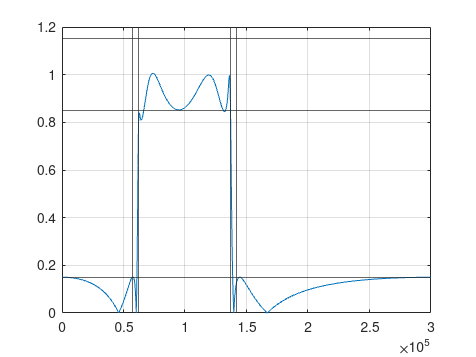

hold on
xline(57000); xline(62000); xline(137000); xline(142000);
yline(0.15); yline(0.85); yline(1.15);
%datatip(h,57000,0,'location','northwest');
%datatip(h,62000,0.85,'location','northwest');
%datatip(h,137000,0.85,'location','northeast');
%datatip(h,142000,0,'location','northeast');
grid on 
ylim([0,1.2])
hold off
saveas(gcf,"Elliptical_bandpass.png")

z=roots(nz)

z =   -0.1752 + 0.9845i
  -0.1752 - 0.9845i
   0.1080 + 0.9941i
   0.1080 - 0.9941i
   0.8858 + 0.4641i
   0.8858 - 0.4641i
   0.8068 + 0.5909i
   0.8068 - 0.5909i


p=roots(dz)

p =    0.1339 + 0.9775i
   0.1339 - 0.9775i
   0.2240 + 0.8215i
   0.2240 - 0.8215i
   0.7896 + 0.5975i
   0.7896 - 0.5975i
   0.6709 + 0.5953i
   0.6709 - 0.5953i


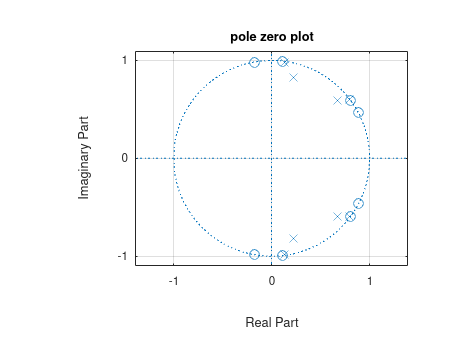

zplane(z,p)
grid on
title('pole zero plot')
saveas(gcf,"elliptical_bandpass_pz.png")

xlim([-1.39 1.39])

function [z,p,H0,B,A] = ellipap2(N,Ap,As)
if nargin==0, help ellipap2; return; end
Gp = 10^(-Ap/20); % passband gain
ep = sqrt(10^(Ap/10) - 1); % ripple factors
es = sqrt(10^(As/10) - 1);
k1 = ep/es;
k = ellipdeg(N,k1); % solve degree equation
L = floor(N/2); r = mod(N,2); % L is the number of second-order sections
i = (1:L); ui = (2*i-1)/N; zeta_i = cde(ui,k); % zeros of elliptic rational function
z = 1i./(k*zeta_i); % filter zeros = poles of elliptic rational function
v0 = -1i*asne(1i/ep, k1)/N; % solution of sn(jv0NK1, k1) = j/εp
p = 1i*cde(ui-1i*v0, k); % filter poles
p0 = 1i*sne(1i*v0, k); % first-order pole, needed when N is odd
B = [transpose(ones(1,L)), transpose(-2*real(1./z)), transpose(abs(1./z).^2)]; % numerator second-order sections
A = [transpose(ones(1,L)), transpose(-2*real(1./p)), transpose(abs(1./p).^2)]; % denominator second-order sections
if r==0 % prepend first-order sections
B = [Gp, 0, 0; B]; A = [1, 0, 0; A];
else
B = [1, 0, 0; B]; A = [1, -real(1/p0), 0; A];
end
z = cplxpair([z; conj(z)]); % append conjugate zeros
p = cplxpair([p; conj(p)]); % append conjugate poles
if r==1, p = [p; p0]; end % append first-order pole when N is odd
H0 = Gp^(1-r); 


end



